files = {'eol.jpg', 'cameraman.tif'};

origin_A = rgb2gray(imread(['./', files{1}]))

origin_A = 1920×1920 uint8 행렬
   217   218   218   220   219   219   218   220   220   220   219   220   222   220   219   221   221   219   220   220   219   221   222   220   220   222   220   218   221   222   220   219   221   221   221   222   221   220   219   220   222   222   223   222   222   223   222   222   222   223
   216   217   217   220   218   219   219   220   219   220   220   220   220   219   219   221   220   219   219   220   220   221   221   220   218   219   219   219   221   222   220   219   219   219   220   221   221   220   220   221   221   222   222   222   222   223   223   223   222   222
   218   217   218   221   219   220   220   220   221   221   222   221   221   221   221   220   220   220   220   220   221   221   221   221   220   220   221   221   220   219   220   219   220   221   222   221   221   221   222   221   219   220   220   220   221   222   223   223   223   222
   219   218   219   222   218   220   220   218   221   219   219 

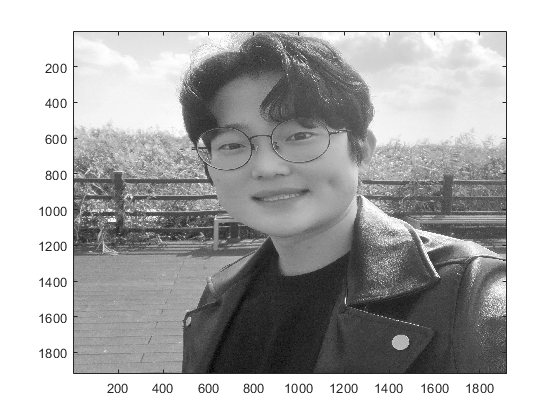


B = myEdgeDetection(origin_A);

H = gausswin(1) * gausswin(10);
gauss_A = filter2(H, origin_A);

C = myEdgeDetection(gauss_A);

figure(1);
imagesc(origin_A); colormap(gray);

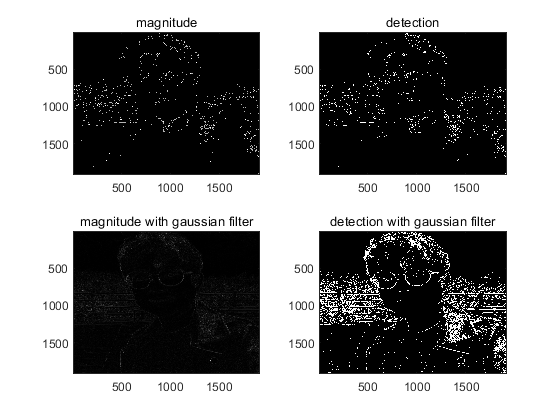


figure(2);
subplot(2, 2, 1);
imagesc(B.magnitude); colormap(gray);
title('magnitude')

subplot(2, 2, 2);
imagesc(B.binary_im); colormap(gray);
title('detection')

subplot(2, 2, 3);
imagesc(C.magnitude); colormap(gray);
title('magnitude with gaussian filter')

subplot(2, 2, 4);
imagesc(C.binary_im); colormap(gray);
title('detection with gaussian filter')



function result = myEdgeDetection(A)
A = A/max(A(:));

[M, N] = size(A);

delta_fx = zeros(M, N);
delta_fy = zeros(M, N);

for m=1:M,
    delta_fx(m, 2:N) = A(m, 2:N) - A(m, 1:N-1);
end

for n=1:N,
    delta_fy(2:M, n) = A(2:M, n) - A(1:M-1, n);
end

angles = atan(delta_fy./delta_fx);

magnitude = sqrt(delta_fy.^2+delta_fx.^2);
thresh = graythresh(magnitude);
binary_im = im2bw(magnitude, thresh);

result.binary_im = binary_im;
result.delta_fx = delta_fx;
result.delta_fy = delta_fy;
result.angles = angles;
result.magnitude = magnitude;

end